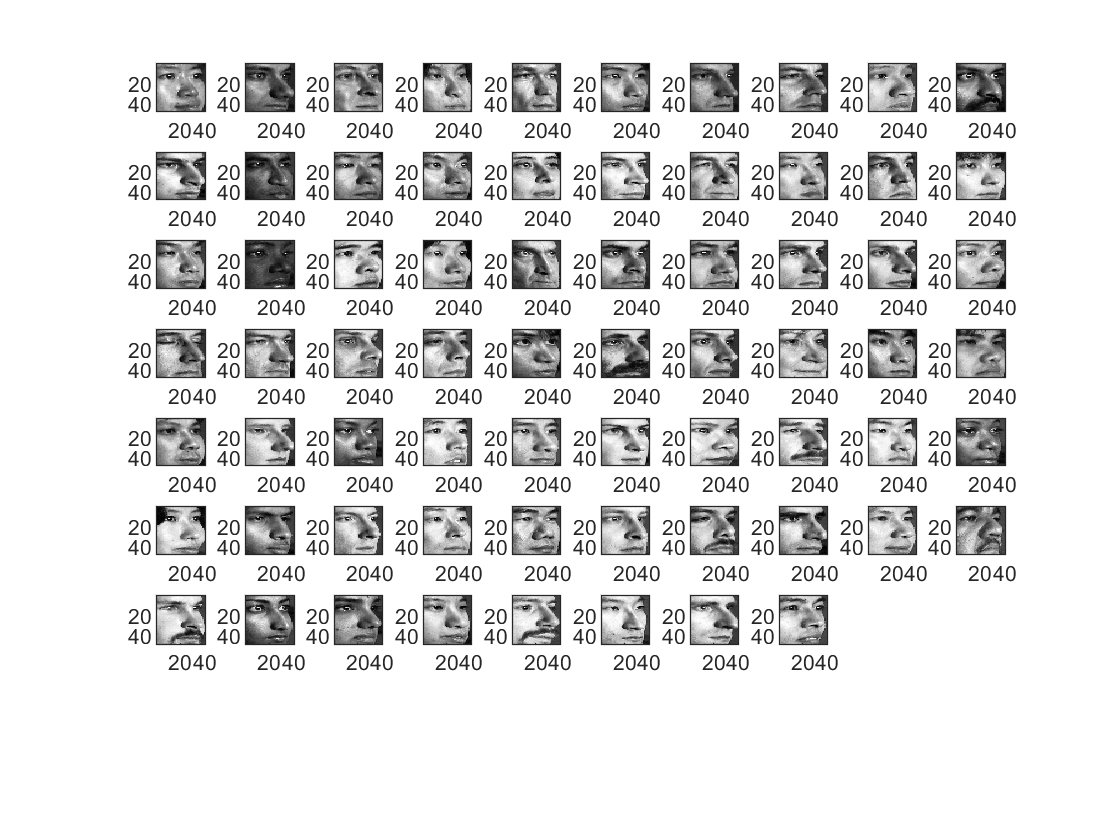

data = load('pose.mat');
pose = data.pose;
% Each image is 48x40 pixel image, there are 13 images for each subject and 68 subjects
figure, clf;
colormap 'gray';
%display the 1st image of each subject
for i=1:68
    subplot(8,10,i);
    imagesc(pose(:,:,1,i)); 
end

## Prepare Train and Test datasets

Using the 1st 10 images for training pupose and testing on remaining 3 for each subject.

trn_sz = 10;
X_trn=zeros(size(pose,1), size(pose,2),1,trn_sz*size(pose,4));
Y_trn=zeros(trn_sz*size(pose,4),1);
for i=1:size(pose,4)
    for j=1:trn_sz
        X_trn(:,:,1,(i-1)*trn_sz + j) = pose(:,:,j,i);
        Y_trn((i-1)*trn_sz + j) = i;
    end
end
X_tst=zeros(size(pose,1), size(pose,2),1,(size(pose,3)-trn_sz)*size(pose,4));
Y_tst=zeros((size(pose,3)-trn_sz)*size(pose,4),1);
for i=1:size(pose,4)
    for j=trn_sz + 1:size(pose,3)
        X_tst(:,:,1,(i-1)*(size(pose,3)-trn_sz)+j-trn_sz) = pose(:,:,j,i);
        Y_tst((i-1)*(size(pose,3)-trn_sz)+j-trn_sz) = i;
    end
end
Y_trn = categorical(Y_trn);
Y_tst = categorical(Y_tst);

options = trainingOptions('sgdm', ...
    'MaxEpochs',50,...
    'InitialLearnRate',1e-3,...
    'MiniBatchSize',10,...
    'ValidationData',{X_tst,Y_tst},...
    'Shuffle',"every-epoch",...
    'Verbose',true, ...
    'Plots','training-progress');

layers = [ ...
    imageInputLayer([48 40 1])
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
%    averagePooling2dLayer(3)
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32)
    batchNormalizationLayer
    reluLayer
% %    averagePooling2dLayer(3)
    maxPooling2dLayer(2,'Stride',1)
    fullyConnectedLayer(68)
    softmaxLayer
    classificationLayer];
[net, info] = trainNetwork(X_trn,Y_trn,layers,options);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |        0.00% |        0.98% |       5.8721 |       5.2514 |          0.0010 |


|       1 |          50 |       00:00:07 |       10.00% |       17.65% |       4.8430 |       4.0939 |          0.0010 |


|       2 |         100 |       00:00:09 |       60.00% |       25.49% |       1.2187 |       2.9823 |          0.0010 |


|       3 |         150 |       00:00:11 |       60.00% |       45.10% |       2.0386 |       2.4114 |          0.0010 |


|       3 |         200 |       00:00:13 |       90.00% |       46.08% |       0.7459 |       1.7785 |          0.0010 |


|       4 |         250 |       00:00:15 |       90.00% |       62.25% |       0.2288 |       1.4903 |          0.0010 |


|       5 |         300 |       00:00:17 |      100.00% |       64.22% |       0.1472 |       1.3855 |          0.0010 |


|       6 |         350 |       00:00:19 |      100.00% |       60.78% |       0.0734 |       1.4060 |          0.0010 |


|       6 |         400 |       00:00:21 |      100.00% |       68.63% |       0.0176 |       1.2192 |          0.0010 |


|       7 |         450 |       00:00:23 |      100.00% |       68.14% |       0.0125 |       1.1842 |          0.0010 |


|       8 |         500 |       00:00:25 |      100.00% |       72.06% |       0.0290 |       1.0877 |          0.0010 |


|       9 |         550 |       00:00:27 |      100.00% |       75.49% |       0.0187 |       1.0040 |          0.0010 |


|       9 |         600 |       00:00:29 |      100.00% |       74.02% |       0.0130 |       1.0088 |          0.0010 |


|      10 |         650 |       00:00:31 |      100.00% |       74.51% |       0.0107 |       0.9942 |          0.0010 |


|      11 |         700 |       00:00:33 |      100.00% |       70.59% |       0.0124 |       1.0568 |          0.0010 |


|      12 |         750 |       00:00:35 |      100.00% |       74.02% |       0.0074 |       1.0389 |          0.0010 |


|      12 |         800 |       00:00:37 |      100.00% |       74.02% |       0.0146 |       0.9974 |          0.0010 |


|      13 |         850 |       00:00:39 |      100.00% |       71.57% |       0.0185 |       1.0276 |          0.0010 |


|      14 |         900 |       00:00:41 |      100.00% |       72.06% |       0.0080 |       0.9778 |          0.0010 |


|      14 |         950 |       00:00:43 |      100.00% |       72.06% |       0.0134 |       0.9916 |          0.0010 |


|      15 |        1000 |       00:00:45 |      100.00% |       75.00% |       0.0066 |       0.9428 |          0.0010 |


|      16 |        1050 |       00:00:47 |      100.00% |       71.08% |       0.0108 |       1.0430 |          0.0010 |


|      17 |        1100 |       00:00:49 |      100.00% |       75.98% |       0.0129 |       0.9555 |          0.0010 |


|      17 |        1150 |       00:00:51 |      100.00% |       71.08% |       0.0051 |       1.0325 |          0.0010 |


|      18 |        1200 |       00:00:53 |      100.00% |       73.04% |       0.0109 |       0.9849 |          0.0010 |


|      19 |        1250 |       00:00:54 |      100.00% |       73.53% |       0.0052 |       0.9956 |          0.0010 |


|      20 |        1300 |       00:00:56 |      100.00% |       75.98% |       0.0064 |       1.0112 |          0.0010 |


|      20 |        1350 |       00:00:58 |      100.00% |       74.51% |       0.0050 |       0.9659 |          0.0010 |


|      21 |        1400 |       00:01:00 |      100.00% |       75.49% |       0.0087 |       0.9625 |          0.0010 |


|      22 |        1450 |       00:01:02 |      100.00% |       72.06% |       0.0120 |       0.9609 |          0.0010 |


|      23 |        1500 |       00:01:04 |      100.00% |       74.51% |       0.0043 |       0.9787 |          0.0010 |


|      23 |        1550 |       00:01:06 |      100.00% |       69.61% |       0.0072 |       1.0755 |          0.0010 |


|      24 |        1600 |       00:01:08 |      100.00% |       72.55% |       0.0166 |       0.9657 |          0.0010 |


|      25 |        1650 |       00:01:10 |      100.00% |       73.04% |       0.0066 |       0.9600 |          0.0010 |


|      25 |        1700 |       00:01:12 |      100.00% |       75.49% |       0.0084 |       0.9358 |          0.0010 |


|      26 |        1750 |       00:01:14 |      100.00% |       72.55% |       0.0036 |       1.0034 |          0.0010 |


|      27 |        1800 |       00:01:16 |      100.00% |       75.98% |       0.0074 |       0.9466 |          0.0010 |


|      28 |        1850 |       00:01:19 |      100.00% |       75.00% |       0.0030 |       0.9004 |          0.0010 |


|      28 |        1900 |       00:01:22 |      100.00% |       75.00% |       0.0062 |       0.9381 |          0.0010 |


|      29 |        1950 |       00:01:25 |      100.00% |       75.49% |       0.0069 |       0.9418 |          0.0010 |


|      30 |        1988 |       00:01:28 |      100.00% |              |       0.0051 |              |          0.0010 |
|======================================================================================================================|


options = trainingOptions('sgdm', ...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-2,...
    'MiniBatchSize',40,...
    'ValidationData',{X_tst,Y_tst},"LearnRateDropFactor",0.9,...
    'Shuffle',"every-epoch",...
    'Verbose',true, ...
    'Plots','training-progress');
rpose = resnet18("Weights","none"); 
rpose = rpose.replaceLayer('data',imageInputLayer([48 40 1],'Name','Input'));
rpose = rpose.replaceLayer('fc1000',fullyConnectedLayer(68,"Name","connect"));

[r_pose, r_info] = trainNetwork(X_trn,Y_trn,rpose,options);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:15 |        0.00% |        2.45% |       4.9021 |       4.7955 |          0.0100 |


|       3 |          50 |       00:01:49 |       70.00% |       44.12% |       0.9174 |       1.9289 |          0.0100 |


|       6 |         100 |       00:03:24 |       97.50% |       68.14% |       0.0596 |       1.0908 |          0.0100 |


|       9 |         150 |       00:04:57 |      100.00% |       72.55% |       0.0050 |       0.9794 |          0.0100 |


|      10 |         170 |       00:05:37 |      100.00% |       71.08% |       0.0135 |       0.9578 |          0.0100 |
|======================================================================================================================|
